% =========================================================================
% EKF-SLAM y Mapa de Ocupación (Log-Odds) para Robot MiR100
% =========================================================================
clear; clc; close all;

%% 1. Cargar el archivo ROSBAG
filePath = 'mir_basics_20251210_114529.bag'; % Reemplaza con tu archivo
disp('Abriendo archivo rosbag...');

Abriendo archivo rosbag...


bag = rosbag(filePath);

% Seleccionar los tópicos relevantes
bagOdom = select(bag, 'Topic', '/odom');
bagScan = select(bag, 'Topic', '/scan');
bagGT   = select(bag, 'Topic', '/base_pose_ground_truth');

% Extraer las marcas de tiempo (Timestamps) de cada tópico
time_odom = bagOdom.MessageList.Time;
time_scan = bagScan.MessageList.Time;
time_gt   = bagGT.MessageList.Time;

% Leer los mensajes
disp('Leyendo mensajes del rosbag...');

Leyendo mensajes del rosbag...


odomMsgs = readMessages(bagOdom, 'DataFormat', 'struct');
scanMsgs = readMessages(bagScan, 'DataFormat', 'struct');
gtMsgs   = readMessages(bagGT, 'DataFormat', 'struct');

%% 1.1 Extraer y Alinear Ground Truth (SINCRONIZADO)
total_scan_msgs = length(scanMsgs);

% Buscar el GT que coincida exactamente con el PRIMER SCAN
[~, first_gt_idx] = min(abs(time_gt - time_scan(1)));

start_gt_pos = [gtMsgs{first_gt_idx}.Pose.Pose.Position.X, gtMsgs{first_gt_idx}.Pose.Pose.Position.Y];
quat_gt = gtMsgs{first_gt_idx}.Pose.Pose.Orientation;
start_gt_yaw = quat2yaw([quat_gt.W, quat_gt.X, quat_gt.Y, quat_gt.Z]);

% Extraemos poses de GT de forma vectorizada y RELATIVA al inicio sincronizado
gt_x = cellfun(@(m) m.Pose.Pose.Position.X - start_gt_pos(1), gtMsgs);
gt_y = cellfun(@(m) m.Pose.Pose.Position.Y - start_gt_pos(2), gtMsgs);

%% 2. Inicialización de Variables y Matrices EKF
%mu = [0; 0; start_gt_yaw]; %original
mu = [0; 0; 0];
%mu = [0; 0; start_gt_yaw - pi/2];
Sigma = diag([0.1, 0.1, deg2rad(5)].^2); 

%R = diag([0.05, 0.05, 0.02].^2);
R = diag([0.01, 0.01, 0.005].^2);

%Q = diag([0.1, deg2rad(1)].^2);  
Q = diag([0.5, deg2rad(5)].^2);


trajectory = zeros(total_scan_msgs, 3);
map_landmarks = []; 

% Sincronizar la primera odometría con el primer scan
[~, first_odom_idx] = min(abs(time_odom - time_scan(1)));
last_odom_pos = [odomMsgs{first_odom_idx}.Pose.Pose.Position.X, odomMsgs{first_odom_idx}.Pose.Pose.Position.Y];
quat_odom = odomMsgs{first_odom_idx}.Pose.Pose.Orientation;
last_odom_yaw = quat2yaw([quat_odom.W, quat_odom.X, quat_odom.Y, quat_odom.Z]);

%se crea una matriz espacial de una resolución de 0.1;
%% 2.1 Inicialización del Mapa de Ocupación Log-Odds
map_res = 0.1; % Resolución del mapa: 10 cm por celda
x_min = -20; x_max = 20; % Límites del mapa en metros
y_min = -20; y_max = 20;
cols = round((x_max - x_min) / map_res);
rows = round((y_max - y_min) / map_res);

log_odds_map = zeros(rows, cols); % Matriz inicializada en 0 (p = 0.5)

% Probabilidades y valores log-odds
p_occ = 0.7;  % Probabilidad si el LiDAR detecta un obstáculo
p_free = 0.3;  % Probabilidad si el rayo atraviesa el espacio libre
l_occ = log(p_occ / (1 - p_occ));
l_free = log(p_free / (1 - p_free));

% Saturación del log-odds para evitar que el mapa sea inamovible (overconfidence)
l_max = 10;
l_min = -10;

%% 3. Bucle Principal de EKF-SLAM y Mapeo
disp('Iniciando EKF-SLAM y Construcción del Mapa (Procesamiento Oculto)...');

Iniciando EKF-SLAM y Construcción del Mapa (Procesamiento Oculto)...



for i = 1:total_scan_msgs

    current_time = time_scan(i);

    % --- A. PREDICCIÓN (Odometría Sincronizada) ---
    [~, idx_odom] = min(abs(time_odom - current_time));
    curr_odom = odomMsgs{idx_odom}; 

    curr_pos = [curr_odom.Pose.Pose.Position.X, curr_odom.Pose.Pose.Position.Y];
    quat_curr = curr_odom.Pose.Pose.Orientation;
    curr_yaw = quat2yaw([quat_curr.W, quat_curr.X, quat_curr.Y, quat_curr.Z]);

    delta_trans = norm(curr_pos - last_odom_pos);
    delta_rot = angdiff(last_odom_yaw, curr_yaw);

    theta = mu(3);
    mu(1) = mu(1) + delta_trans * cos(theta + delta_rot/2);
    mu(2) = mu(2) + delta_trans * sin(theta + delta_rot/2);
    mu(3) = wrapToPi(mu(3) + delta_rot);

    N = length(mu);
    Fx = [eye(3), zeros(3, N-3)]; 

    G_t = eye(N) + Fx' * [0, 0, -delta_trans * sin(theta + delta_rot/2);
                          0, 0,  delta_trans * cos(theta + delta_rot/2);
                          0, 0,  0] * Fx;

    Sigma = G_t * Sigma * G_t' + Fx' * R * Fx;

    last_odom_pos = curr_pos;
    last_odom_yaw = curr_yaw;

    % --- B. EXTRACCIÓN DE CARACTERÍSTICAS (Para EKF) ---
    scan = scanMsgs{i};
    [z_ranges, z_angles] = extractLandmarksFromScan(scan);

    % --- C. ACTUALIZACIÓN EKF ---
    for j = 1:length(z_ranges)
        r_meas = z_ranges(j);
        phi_meas = z_angles(j);

        m_x_est = mu(1) + r_meas * cos(mu(3) + phi_meas);
        m_y_est = mu(2) + r_meas * sin(mu(3) + phi_meas);

        best_idx = 0;
        min_dist_sq = 1e6;
        distance_threshold = 0.5; 

        if length(mu) > 3
            landmarks = [mu(4:2:end), mu(5:2:end)];
            for k = 1:size(landmarks, 1)
                dist_sq = (landmarks(k, 1) - m_x_est)^2 + (landmarks(k, 2) - m_y_est)^2;
                if dist_sq < min_dist_sq
                    min_dist_sq = dist_sq;
                    best_idx = k;
                end
            end
        end

        if best_idx > 0 && min_dist_sq < distance_threshold^2
            idx = best_idx;
        else
            map_landmarks = [map_landmarks; length(map_landmarks) + 1]; 
            mu = [mu; m_x_est; m_y_est];
            Sigma = blkdiag(Sigma, eye(2)*100); 
            idx = length(map_landmarks);
        end

        lm_idx_x = 3 + 2*(idx-1) + 1;
        lm_idx_y = 3 + 2*idx;

        delta_x = mu(lm_idx_x) - mu(1);
        delta_y = mu(lm_idx_y) - mu(2);
        q = delta_x^2 + delta_y^2;

        z_hat = [sqrt(q); wrapToPi(atan2(delta_y, delta_x) - mu(3))];

        N = length(mu);
        Fx_j = zeros(5, N);
        Fx_j(1:3, 1:3) = eye(3);
        Fx_j(4:5, lm_idx_x:lm_idx_y) = eye(2);

        h_matrix = [-delta_x/sqrt(q), -delta_y/sqrt(q), 0, delta_x/sqrt(q), delta_y/sqrt(q);
                     delta_y/q,       -delta_x/q,      -1, -delta_y/q,       delta_x/q];

        H_t = h_matrix * Fx_j;
        S = H_t * Sigma * H_t' + Q;
        K = Sigma * H_t' / S;

        innov = [r_meas - z_hat(1); wrapToPi(phi_meas - z_hat(2))];
        mu = mu + K * innov;
        Sigma = (eye(N) - K * H_t) * Sigma;
    end

    trajectory(i, :) = mu(1:3)';

    % --- D. ACTUALIZACIÓN DEL MAPA DE OCUPACIÓN (Log-Odds) ---
    all_ranges = double(scan.Ranges);
    angle_min = double(scan.AngleMin);
    angle_inc = double(scan.AngleIncrement);
    all_angles = angle_min + (0:length(all_ranges)-1)' * angle_inc;
    
    % Filtrar lecturas válidas del escáner completo (no solo landmarks)
    max_range = 15.0; % Rango máximo confiable
    valid_scan_idx = isfinite(all_ranges) & all_ranges > 0.1 & all_ranges < max_range;
    r_valid = all_ranges(valid_scan_idx);
    a_valid = all_angles(valid_scan_idx);
    
    % Posición del robot en celdas de la matriz
    rob_x_grid = round((mu(1) - x_min) / map_res) + 1;
    rob_y_grid = round((mu(2) - y_min) / map_res) + 1;
    
    for k = 1:length(r_valid)
        % Coordenadas del obstáculo en el mundo (usando la pose EKF corregida)
        obs_x = mu(1) + r_valid(k) * cos(mu(3) + a_valid(k));
        obs_y = mu(2) + r_valid(k) * sin(mu(3) + a_valid(k));
        
        % Coordenadas del obstáculo en celdas de la matriz
        obs_x_grid = round((obs_x - x_min) / map_res) + 1;
        obs_y_grid = round((obs_y - y_min) / map_res) + 1;
        
        % Trazado de rayos (pseudo-Bresenham rápido)
        [ray_x, ray_y] = get_ray_cells(rob_x_grid, rob_y_grid, obs_x_grid, obs_y_grid);
        
        % Filtrar puntos que caen dentro de los límites del mapa
        valid_ray_idx = ray_x > 0 & ray_x <= cols & ray_y > 0 & ray_y <= rows;
        ray_x = ray_x(valid_ray_idx);
        ray_y = ray_y(valid_ray_idx);
        
        if isempty(ray_x); continue; end
        
        % Índices lineales para actualización rápida
        lin_idx = sub2ind([rows, cols], ray_y, ray_x);
        
        % Actualizar espacio libre (todo el rayo excepto el último punto)
        if length(lin_idx) > 1
            log_odds_map(lin_idx(1:end-1)) = log_odds_map(lin_idx(1:end-1)) + l_free;
        end
        
        % Actualizar espacio ocupado (solo el último punto si hubo impacto)
        log_odds_map(lin_idx(end)) = log_odds_map(lin_idx(end)) + l_occ;
    end
    
    % --- E. VISUALIZACIÓN EN TIEMPO REAL (COMENTADA PARA EFICIENCIA) ---
    %{
    if mod(i, 20) == 0 
        ... Tu código original de graficación iba aquí ...
    end
    %}
    
    % Imprimir progreso
    if mod(i, 100) == 0
        fprintf('Procesados %d de %d scans...\n', i, total_scan_msgs);
    end
end

Procesados 100 de 10003 scans...
Procesados 200 de 10003 scans...
Procesados 300 de 10003 scans...
Procesados 400 de 10003 scans...
Procesados 500 de 10003 scans...
Procesados 600 de 10003 scans...
Procesados 700 de 10003 scans...
Procesados 800 de 10003 scans...
Procesados 900 de 10003 scans...
Procesados 1000 de 10003 scans...
Procesados 1100 de 10003 scans...
Procesados 1200 de 10003 scans...
Procesados 1300 de 10003 scans...
Procesados 1400 de 10003 scans...
Procesados 1500 de 10003 scans...
Procesados 1600 de 10003 scans...
Procesados 1700 de 10003 scans...
Procesados 1800 de 10003 scans...
Procesados 1900 de 10003 scans...
Procesados 2000 de 10003 scans...
Procesados 2100 de 10003 scans...
Procesados 2200 de 10003 scans...
Procesados 2300 de 10003 scans...
Procesados 2400 de 10003 scans...
Procesados 2500 de 10003 scans...
Procesados 2600 de 10003 scans...
Procesados 2700 de 10003 scans...
Procesados 2800 de 10003 scans...
Procesados 2900 de 10003 scans...
Procesados 3000 de 1000

disp('Simulación Finalizada. Generando el mapa...');

Simulación Finalizada. Generando el mapa...


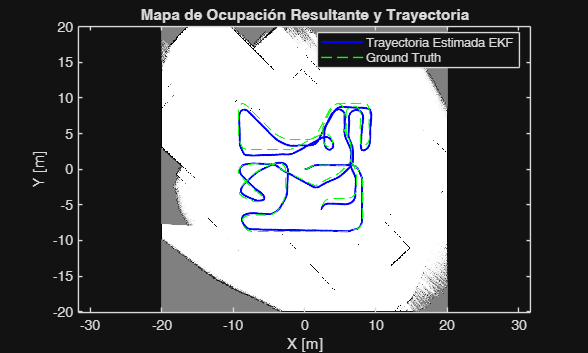


%% 4. Convertir Log-Odds a Probabilidad y Visualizar el Resultado Final
% Saturación de seguridad
log_odds_map = max(min(log_odds_map, l_max), l_min);

% Transformar log-odds a probabilidad p = 1 - 1/(1 + exp(l))
prob_map = 1 - (1 ./ (1 + exp(log_odds_map)));

figure('Name', 'Mapa de Ocupación EKF-SLAM', 'NumberTitle', 'off');
% Utilizamos imagesc invirtiendo el eje Y para alinear con coordenadas del mundo
imagesc([x_min x_max], [y_min y_max], 1 - prob_map); 
colormap(gray); % Blanco = Libre, Negro = Ocupado, Gris = Desconocido
axis equal xy; 
hold on;
plot(trajectory(:,1), trajectory(:,2), 'b-', 'LineWidth', 1.5);
plot(gt_x, gt_y, 'g--', 'LineWidth', 1);
legend('Trayectoria Estimada EKF', 'Ground Truth', 'Location', 'best');
title('Mapa de Ocupación Resultante y Trayectoria');
xlabel('X [m]'); ylabel('Y [m]');



%% ========================================================================
% FUNCIONES AUXILIARES
% =========================================================================

function [x, y] = get_ray_cells(x1, y1, x2, y2)
    % Aproximación vectorizada rápida de trazado de rayos (Bresenham-like)
    n_points = max(abs(x2 - x1), abs(y2 - y1)) + 1;
    x = round(linspace(x1, x2, n_points));
    y = round(linspace(y1, y2, n_points));
end

function yaw = quat2yaw(q)
    yaw = atan2(2*(q(1)*q(4) + q(2)*q(3)), 1 - 2*(q(3)^2 + q(4)^2));
end

function diff = angdiff(th1, th2)
    diff = wrapToPi(th2 - th1);
end

function [r, phi] = extractLandmarksFromScan(scanMsg)
    threshold = 0.15; 
    ranges = double(scanMsg.Ranges);
    angle_min = double(scanMsg.AngleMin);
    angle_increment = double(scanMsg.AngleIncrement);
    angles = angle_min + (0:length(ranges)-1) * angle_increment;
    valid_indices = isfinite(ranges); 
    x_local = ranges(valid_indices) .* cos(angles(valid_indices));
    y_local = ranges(valid_indices) .* sin(angles(valid_indices));
    points = [x_local', y_local'];
    if size(points, 1) < 5
        r = []; phi = []; return;
    end
    corners = split_and_merge(points, threshold);
    if isempty(corners)
        r = []; phi = [];
    else
        r = sqrt(corners(:,1).^2 + corners(:,2).^2);
        phi = atan2(corners(:,2), corners(:,1));
    end
end

function corners = split_and_merge(points, threshold)
    if size(points, 1) < 2
        corners = [];
        return;
    end
    p1 = points(1, :);
    p2 = points(end, :);
    max_dist = 0;
    idx_split = 0;
    for k = 2:(size(points, 1) - 1)
        pk = points(k, :);
        cross_product = abs((p2(1) - p1(1))*(pk(2) - p1(2)) - (p2(2) - p1(2))*(pk(1) - p1(1)));
        line_length = sqrt((p2(1) - p1(1))^2 + (p2(2) - p1(2))^2);
        if line_length == 0
            dist = sqrt((pk(1) - p1(1))^2 + (pk(2) - p1(2))^2);
        else
            dist = cross_product / line_length;
        end
        if dist > max_dist
            max_dist = dist;
            idx_split = k;
        end
    end
    if max_dist > threshold
        corners_left = split_and_merge(points(1:idx_split, :), threshold);
        corners_right = split_and_merge(points(idx_split:end, :), threshold);
        corners = [corners_left; points(idx_split, :); corners_right];
        corners = unique(corners, 'rows', 'stable'); 
    else
        corners = []; 
    end
end